In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$q1 = \frac{R^{2}\,g^{2}\,m}{V^{2}\,c}$$

$$q2 = -\frac{2\,R\,g}{V}$$

$$q3 = -\frac{R}{L}$$

$$q4 = \frac{1}{L}$$

$$q1 = \frac{7.1e+6}{V^{2}}$$

$$q2 = -\frac{540.0}{V}$$

$$q3 = -\frac{554}{13}$$

$$q4 = \frac{20}{13}$$

v =   106.0200  107.0200  108.0200  109.0200  110.0200  111.0200


x =   631.6591  619.9097  608.4852  597.3736  586.5635  576.0443


y =    -5.0934   -5.0458   -4.9991   -4.9532   -4.9082   -4.8640


z = 0

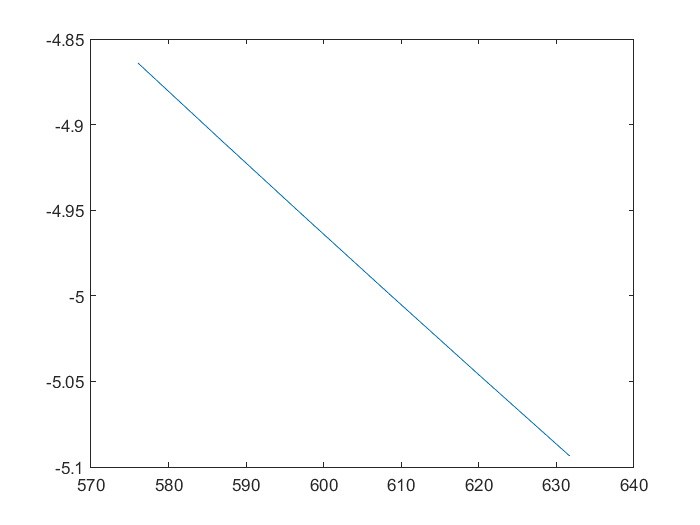

$$A1 = \left(\begin{array}{ccc} 0 & 1 & 0\\ 628.85567847193797563262081120614 & 0 & -5.1261460099708716884196378041879\\ 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$A2 = \left(\begin{array}{ccc} 0 & 1 & 0\\ 563.7976096499271624359951925461 & 0 & -4.8537465390471717103353576850942\\ 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ 1.5384615384973585605621337890625 \end{array}\right)$$


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.026473
     2                        0.010158
     3                        0.010158
     4                        0.010158
     5                    2.048271e-03
     6                    9.697540e-04
     7                    4.979029e-04
     8                    4.979029e-04
     9                    3.130235e-04
    10                    3.130235e-04
    11                    3.822166e-05
    12                    -4.393733e-06

 Result:  best value of t: -4.393733e-06
          f-radius saturation:  0.000% of R =  1.00e+09
 


K = 	1.0e+03 *

    1.0477    0.0894    0.0193


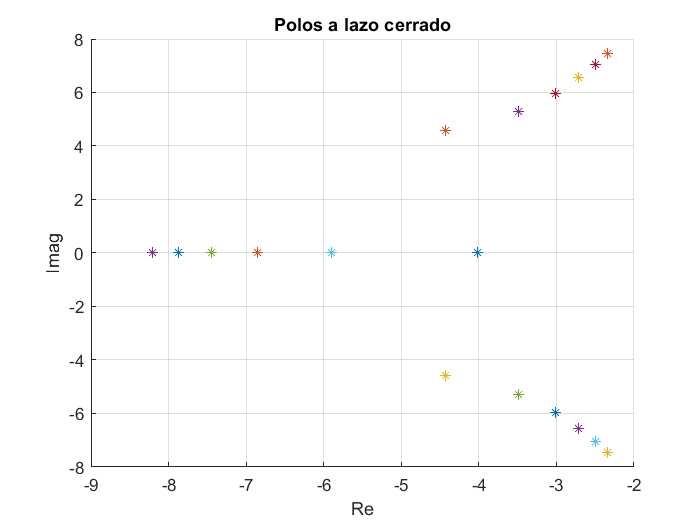

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)

% Se sustituyeron los valores netos de
% http://dx.doi.org/10.1080/00207729608929322 
% R = 27.7 Ohm , L = 0.65 H, c = 1.24 * 10^-4 Nm^2 A^2, M =11.87gr=0.01187Kg, 
% se variara la tensión del punto de equilibrio de 106,02V a 111,97V, lo
% cual deberia permitir tener un control robusto de la planta para
% posiciones entre 15,6mm a 17.4mm

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2)
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)))
%q3 A(3,3)
q3 = -R/L
%q4 B(3,1)
q4 = 1/L

% Sustituimos los valores por defecto 

q1 = vpa(subs(q1, [c g m R], [1.24e-4 9.81 0.01187 27.7]), 2)

q2 = vpa(subs(q2, [c g m R], [1.24e-4 9.81 0.01187 27.7]), 2)

q3 = subs(q3, [R L], [27.7 0.65])

q4 = subs(q4, L, 0.65)
% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

%q4 pertenece a:


figure
for  v=106.02:1:111.97
    q1V = subs(q1, V, v);
    q2V = subs(q2, V, v);
    A=[0 1 0; q1V 0 q2V; 0 0 q3];
    p=eig(A);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off



% politopo 
v=106.02:1:111.97

x=7.1e+6./v.^2
y=-540./v
z= 0
r=plot(x,y);



% % Creamos la desigualdad lineal matricial 
% 
% 
% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
% y = 0.0156m
A1=[0 1 0;subs(q1, V, 106.02) 0 subs(q2, V, 106.02); 0 0 q3]
% y = 0.0174m
A2=[0 1 0;subs(q1, V, 111.97) 0 subs(q2, V, 111.97); 0 0 q3]

B=[0; 0; vpa(q4,2)]

% Especificaciones región reubicación de polos
Alfa=0;
Ro=9;

% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[3 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 3]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 R],B,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);


% Restricciones asociadas al parámetro Ro

% (A,B1)
lmiterm([6 1 1 S],-Ro,1);
lmiterm([6 1 2 S],A1,1);
lmiterm([6 1 2 R],B,1);
lmiterm([6 2 2 S],-Ro,1);

% (A,B2)
lmiterm([7 1 1 S],-Ro,1);
lmiterm([7 1 2 S],A2,1);
lmiterm([7 1 2 R],B,1);
lmiterm([7 2 2 S],-Ro,1);


% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);

K=R*inv(S)



% Polos a lazo cerrado del sistema  politópico

figure
for  v=106.02:1:111.97
    q1F = subs(q1, V, v);
    q2F = subs(q2, V, v);
    A=[0 1 0; q1F 0 q2F; 0 0 q3];
    p=eig(A + B*K);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off


